# Hobbing - Anwendung der Mathematik

## Definition

Modul?

m=3;

al_n= 20;

### Parameter Verzahnung

#### Wälzkreisdurchmesser

d_WZ= 40;

#### Zähnezahlen

z_WZ= 1;
z_WST= 24;

h_f0f =1.4;
h_a0f= 1.17;

### Werkzeuggeometrie

#### Berechnung von Parametern der Werkzeuggeometrie?

[phi_WZ,r_WZ,h_WZ] = WZ(d_WZ, m, al_n, h_a0f, h_f0f, z_WZ);

be = -0.0749

r_WZ_basis =    15.8000   23.5100   23.5100   15.8000


h_WZ_basis =    -3.8849   -1.0787    1.0787    3.8849


phi_WZ_basis =     0.0184    0.0034   -0.0034   -0.0184


h_WZ_basis =    -3.8740   -1.0756    1.0756    3.8740


phi_WZ =     0.0184    0.0034   -0.0034   -0.0184


r_WZ =    15.8000   23.5100   23.5100   15.8000


h_WZ =    -3.8740   -1.0756    1.0756    3.8740


#### Parametrierung der Transformationsmatrizen

Werte der Transformationsmatrix der Maschine

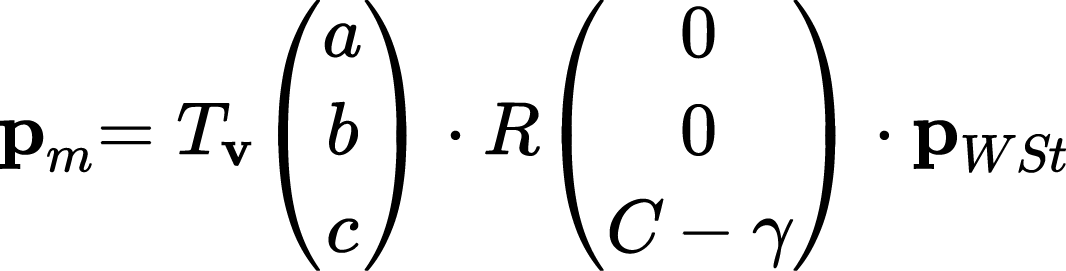

a=0;
b=0;
c=0;
ga=0;

Werte der Transformationsmatrix eines Werkzeugpunktes

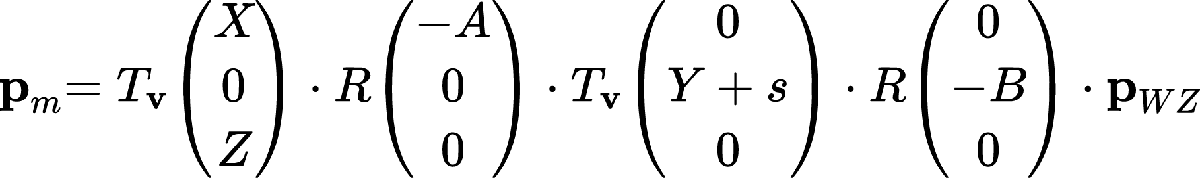

X= m*z_WST/2 + d_WZ/2;
Y=0; 
Z=-5;
Y_shift=0;

#### Winkel A

Vorzeichen:

- doppelter Negativ?

- beim Definieren der Rotationsmatrix wird der Winkel positiv eingeführt

- Rotation ist allerdings mathematisch positiv um x-Achse

A = -atan2(m,d_WZ);

#### Vorschübe?

festhalten (Scherbarths Annäherung?)

fX_WZrad=0;
fY_WZrad=0;

Einheit?

fZ_WZrad= -10/(2*pi);

1/[Zähnezahl] -> Verwendung des Vorschubes so im Simscape Modell?

fC_WSTrad= -1/z_WST;

## CAD Daten des Zahnrads

laden

gear.path = "D:\git\ba\scherbarth";
gear.name = "m3z24h10.stl";
m3z24h10 = stlread(fullfile(gear.path,gear.name));

Koordinaten des Werkstücks in getrennte Variablen

x_WST= m3z24h10.Points(:,1);
y_WST= m3z24h10.Points(:,2);
z_WST= -m3z24h10.Points(:,3);

Soll z-Position

z_soll= -6;

## Berechnung des Verfahrwinkels B

#### Alternativ mit fzero

p_z = p_WST(3)

$$p\_z = z-c+B\,{\mathrm{fZ}}_{\mathrm{WZrad}}+\sin\left(A\right)\,\left(Y_{\mathrm{shift}}+y+B\,{\mathrm{fY}}_{\mathrm{WZrad}}\right)+h_{\mathrm{WZ}}\,\sin\left(A\right)+r_{\mathrm{WZ}}\,\cos\left(A\right)\,\cos\left(B\right)\,\sin\left(\varphi_{\mathrm{WZ}}\right)+r_{\mathrm{WZ}}\,\cos\left(A\right)\,\sin\left(B\right)\,\cos\left(\varphi_{\mathrm{WZ}}\right)$$

B = 2.9876

Dauer Lösung mit fzero: 0.0366 sec.


#### Alternativ: Schleife über asin

tic
B_0= pi*0.75;
B= phi_WZ + pi + asin((Z - c - z_soll + B_0*fZ_WZrad + sin(A)*(Y + Y_shift + B_0*fY_WZrad) + h_WZ*sin(A))./(r_WZ*cos(A)))

B =     3.0032    3.0309    3.0171    2.9291


n = 0;
while sum(abs(B-B_0)) > 0.001
    n = n+1;
    conv(n) = sum(abs(B-B_0));
    B_0= B;
    B=  phi_WZ + pi + asin((Z - c - z_soll + B_0*fZ_WZrad + sin(A)*(Y + Y_shift + B_0*fY_WZrad) + h_WZ*sin(A))./(r_WZ*cos(A)))
end

B =     2.9366    2.9847    2.9718    2.8697


B =     2.9435    2.9878    2.9749    2.8759


B =     2.9428    2.9876    2.9747    2.8752


B =     2.9429    2.9876    2.9747    2.8753


toc

Elapsed time is 0.026451 seconds.


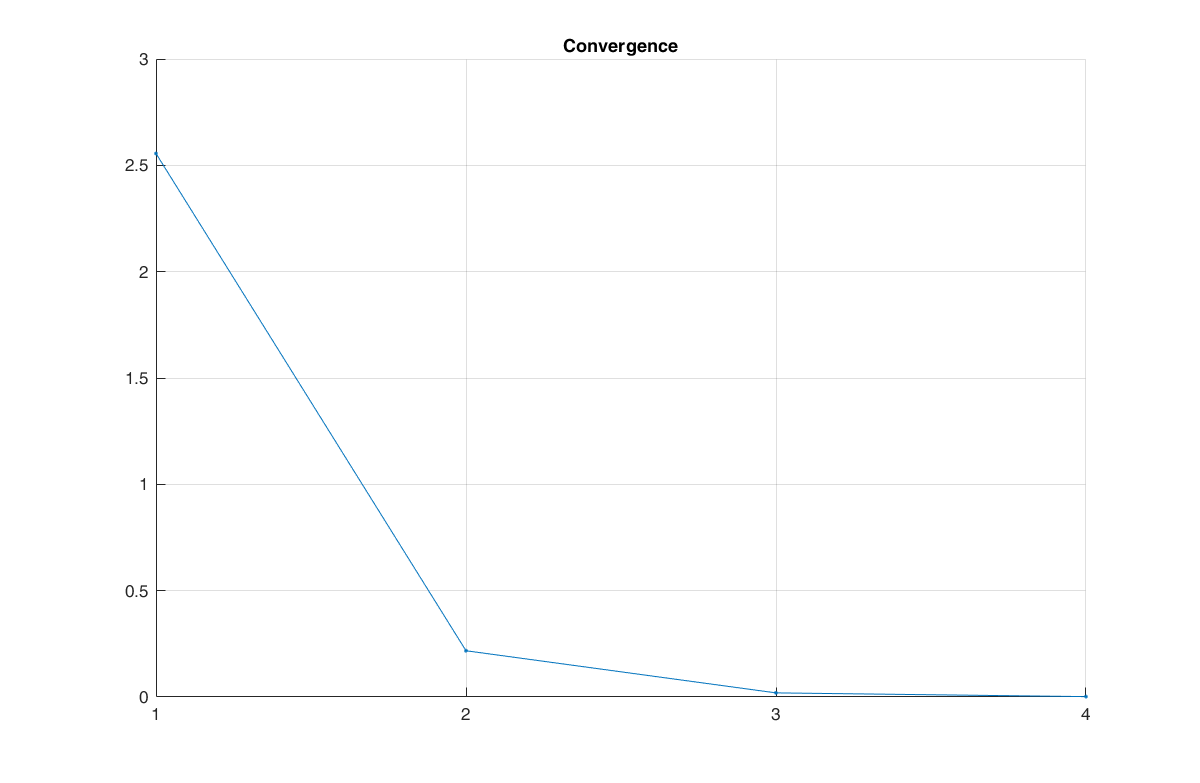

[figH,axH] = getFigH(2,'Color','white'); set(0,'CurrentFigure',figH(1));
line((1:n),conv,'LineStyle','-','Marker','.')
grid on; set(axH(1),"XTick",1:n); axH(1).Title.String = "Convergence";

B=B(1,2)

B = 2.9876

Berechung Werkzeugposition nach Verfahrwinkel B

x_WZm= X - a + B*fX_WZrad + cos(B)*r_WZ.*cos(phi_WZ) - sin(B)*r_WZ.*sin(phi_WZ); 
y_WZm= cos(A)*(Y + Y_shift + B*fY_WZrad) - b + h_WZ*cos(A) - sin(A)*cos(B)*r_WZ.*sin(phi_WZ) - sin(A)*sin(B)*r_WZ.*cos(phi_WZ); 
z_WZm= Z - c + B*fZ_WZrad + sin(A)*(Y + Y_shift + B*fY_WZrad) + h_WZ*sin(A) + cos(A)*r_WZ.*sin(B-phi_WZ);

Berechung Werkstückposition nach Verfahrwinkel B

x_WSTm= x_WST*cos(ga + B*fC_WSTrad) - y_WST*sin(ga + B*fC_WSTrad);
y_WSTm= x_WST*sin(ga + B*fC_WSTrad) + y_WST*cos(ga + B*fC_WSTrad);
z_WSTm= z_WST;

## Plotten

set(0,'CurrentFigure',figH(2));
axis vis3d; grid on; grid minor;
hold on;
lim = 43; xlim([-lim lim]); ylim([-lim lim]);
zlim([-10 10]);
view([62.5 36.3])

Werkzeug

fill3(x_WZm', y_WZm', z_WZm','r')

Werkstück, rotiert

Zahnrad = triangulation(m3z24h10.ConnectivityList,x_WSTm(:),y_WSTm(:),z_WSTm(:));
trH(1) = trisurf(Zahnrad);
trH(1).FaceColor = 'c';
trH(1).EdgeAlpha = 0.2;

Werkstück, Ausgangsposition

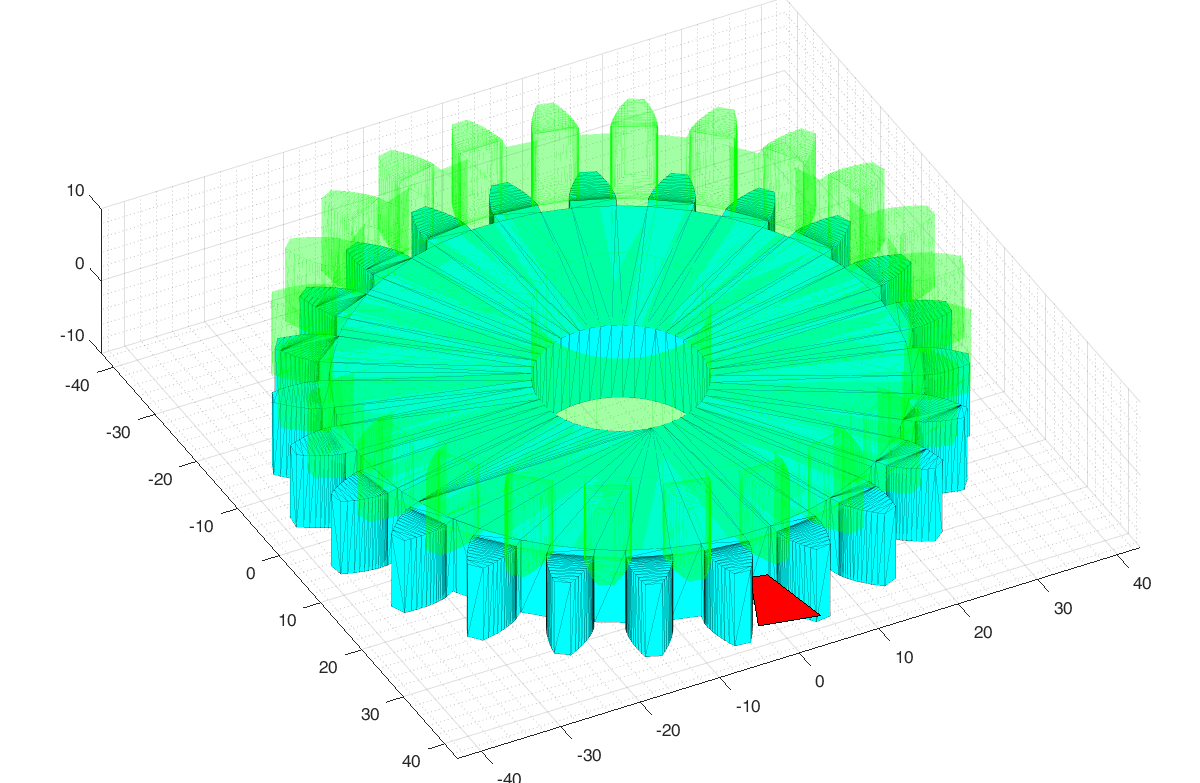

trH(2) = trisurf(m3z24h10);
trH(2).FaceColor ='g';
trH(2).FaceAlpha = 0.2;
trH(2).EdgeColor = 'g';
trH(2).EdgeAlpha = 0.2;